clear all;
clc;

disp("Independent work 07 - interpolation 02.");

Independent work 07 - interpolation 02.



disp("Question 01.");

Question 01.



% Given data points
x = [-1.5, -0.5, 1, 2.5];
y = [92.7, 65.2, 111, 45.5];

% 1. Form the divided difference table
n = length(x);
div_diff_table = zeros(n, n);
div_diff_table(:, 1) = y';

for j = 2:n
    for i = 1:n-j+1
        div_diff_table(i,j) = (div_diff_table(i+1,j-1) - div_diff_table(i,j-1)) / (x(i+j-1) - x(i));
    end
end

disp('Divided Difference Table:');

Divided Difference Table:


disp(div_diff_table);

   92.7000  -27.5000   23.2133  -11.9867
   65.2000   30.5333  -24.7333         0
  111.0000  -43.6667         0         0
   45.5000         0         0         0




% 2. Obtain Newton interpolating polynomials
syms xi;
P1 = div_diff_table(1,1);
P2 = P1 + div_diff_table(1,2)*(xi - x(1));
P3 = P2 + div_diff_table(1,3)*(xi - x(1))*(xi - x(2));
P4 = P3 + div_diff_table(1,4)*(xi - x(1))*(xi - x(2))*(xi - x(3));

disp('First Degree Newton Interpolating Polynomial:');

First Degree Newton Interpolating Polynomial:


disp(P1);

   92.7000



disp('Second Degree Newton Interpolating Polynomial:');

Second Degree Newton Interpolating Polynomial:


disp(P2);

$$\frac{1029}{20}-\frac{55\,\xi }{2}$$

disp('Third Degree Newton Interpolating Polynomial:');

Third Degree Newton Interpolating Polynomial:


disp(P3);

$$\left(\frac{1741\,\xi }{75}+\frac{1741}{50}\right)\,\left(\xi +\frac{1}{2}\right)-\frac{55\,\xi }{2}+\frac{1029}{20}$$

disp('Fourth Degree Newton Interpolating Polynomial:');

Fourth Degree Newton Interpolating Polynomial:


disp(P4);

$$\left(\frac{1741\,\xi }{75}+\frac{1741}{50}\right)\,\left(\xi +\frac{1}{2}\right)-\frac{55\,\xi }{2}-\left(\frac{899\,\xi }{75}+\frac{899}{50}\right)\,\left(\xi -1\right)\,\left(\xi +\frac{1}{2}\right)+\frac{1029}{20}$$

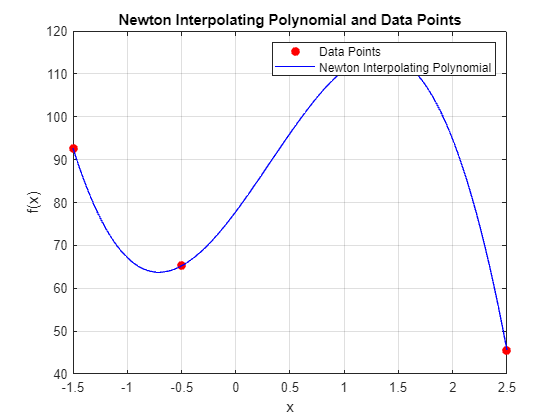


% 3. Plot the Newton interpolating polynomial and interpolation points
x_vals = linspace(min(x), max(x), 100);
P4_vals = double(subs(P4, xi, x_vals));

figure;
plot(x, y, 'ro', 'MarkerFaceColor', 'r');
hold on;
plot(x_vals, P4_vals, 'b-');
legend('Data Points', 'Newton Interpolating Polynomial');
title('Newton Interpolating Polynomial and Data Points');
xlabel('x');
ylabel('f(x)');
grid on;
hold off;


% 4. Calculate f(-0.7), f(1.9) using Newton interpolating polynomial
f_neg_0_7 = double(subs(P4, xi, -0.7));
f_1_9 = double(subs(P4, xi, 1.9));
disp(['f(-0.7) = ', num2str(f_neg_0_7)]);

f(-0.7) = 63.7255


disp(['f(1.9) = ', num2str(f_1_9)]);

f(1.9) = 100.5907
